# EXAMEN 1: Alexis Luna Delgado

## Ejercicio 5


Tp = 1/9450;
P=[0.0, 0.245, 0.445, 0.545, 0.745, 0.845, 0.945, 0.99, 0.99, 0.945,0.845,0.745,0.545,0.445,0.245];

mp = numel(P)

mp = 15

% a)
Ts = Tp / mp

Ts = 7.0547e-06

% b)
Fs = 1 / Ts

Fs = 141750

% c)
Ep = Ts*sum(P.^2); %Calculo de Energia
% d

% e)


## Ejercicio 6

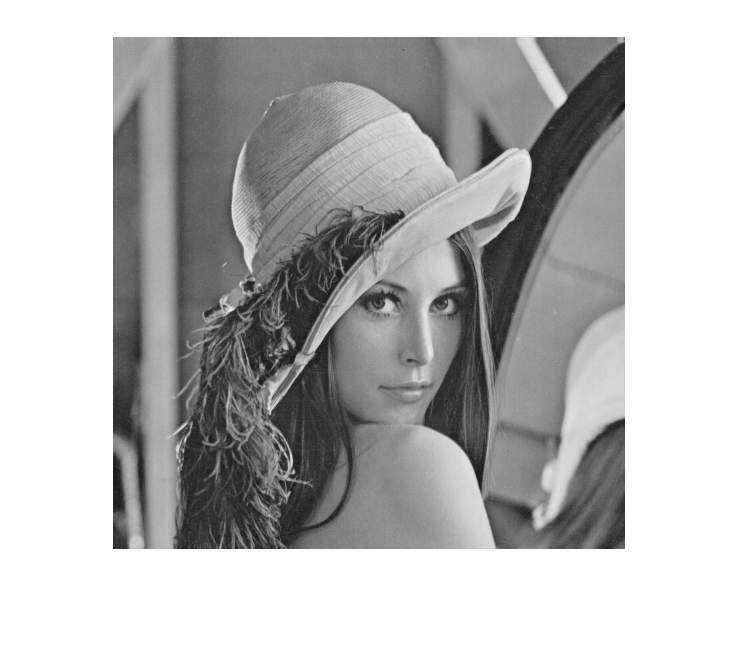

load lena512.mat 
imshow(uint8(lena512)) 

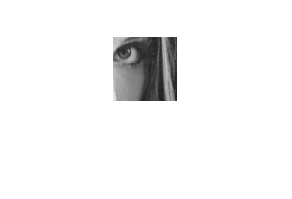

lenarec=lena512(252:315,318:381); 

imshow(uint8(lenarec)) 

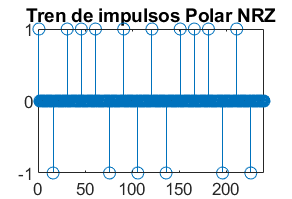

b = de2bi(lenarec,8,'left-msb');
b=b'; 
bits=b(:);   % Vector de bits concatenado 


%Baud_rate= Fs/mp %Symbols per second
%Bit_rate=Baud_rate % bits/s
pnrz=P;
s1=bits;
s1(s1==0)=-1;
s=zeros(1,numel(s1)*mp);
s(1:mp:end)=s1; %Impulse train
stem(s(1:mp*16))
title('Tren de impulsos Polar NRZ');

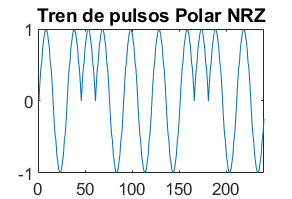

xPNRZ=conv(pnrz,s); %Pulse train
plot(xPNRZ(1:mp*16))
title('Tren de pulsos Polar NRZ');

%pwelch(xPNRZ,500,300,500,Fs,'power');
%%wvtool(xPNRZ)


## Ejercicio 7

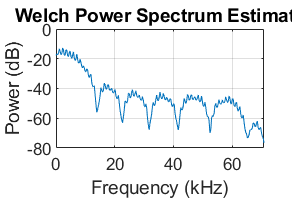

pwelch(xPNRZ,500,300,500,Fs,'power');

%% EL VALOR EN Hz DEL PRIMER NULO DEL ESPECTRO ES 13.8915 KHz


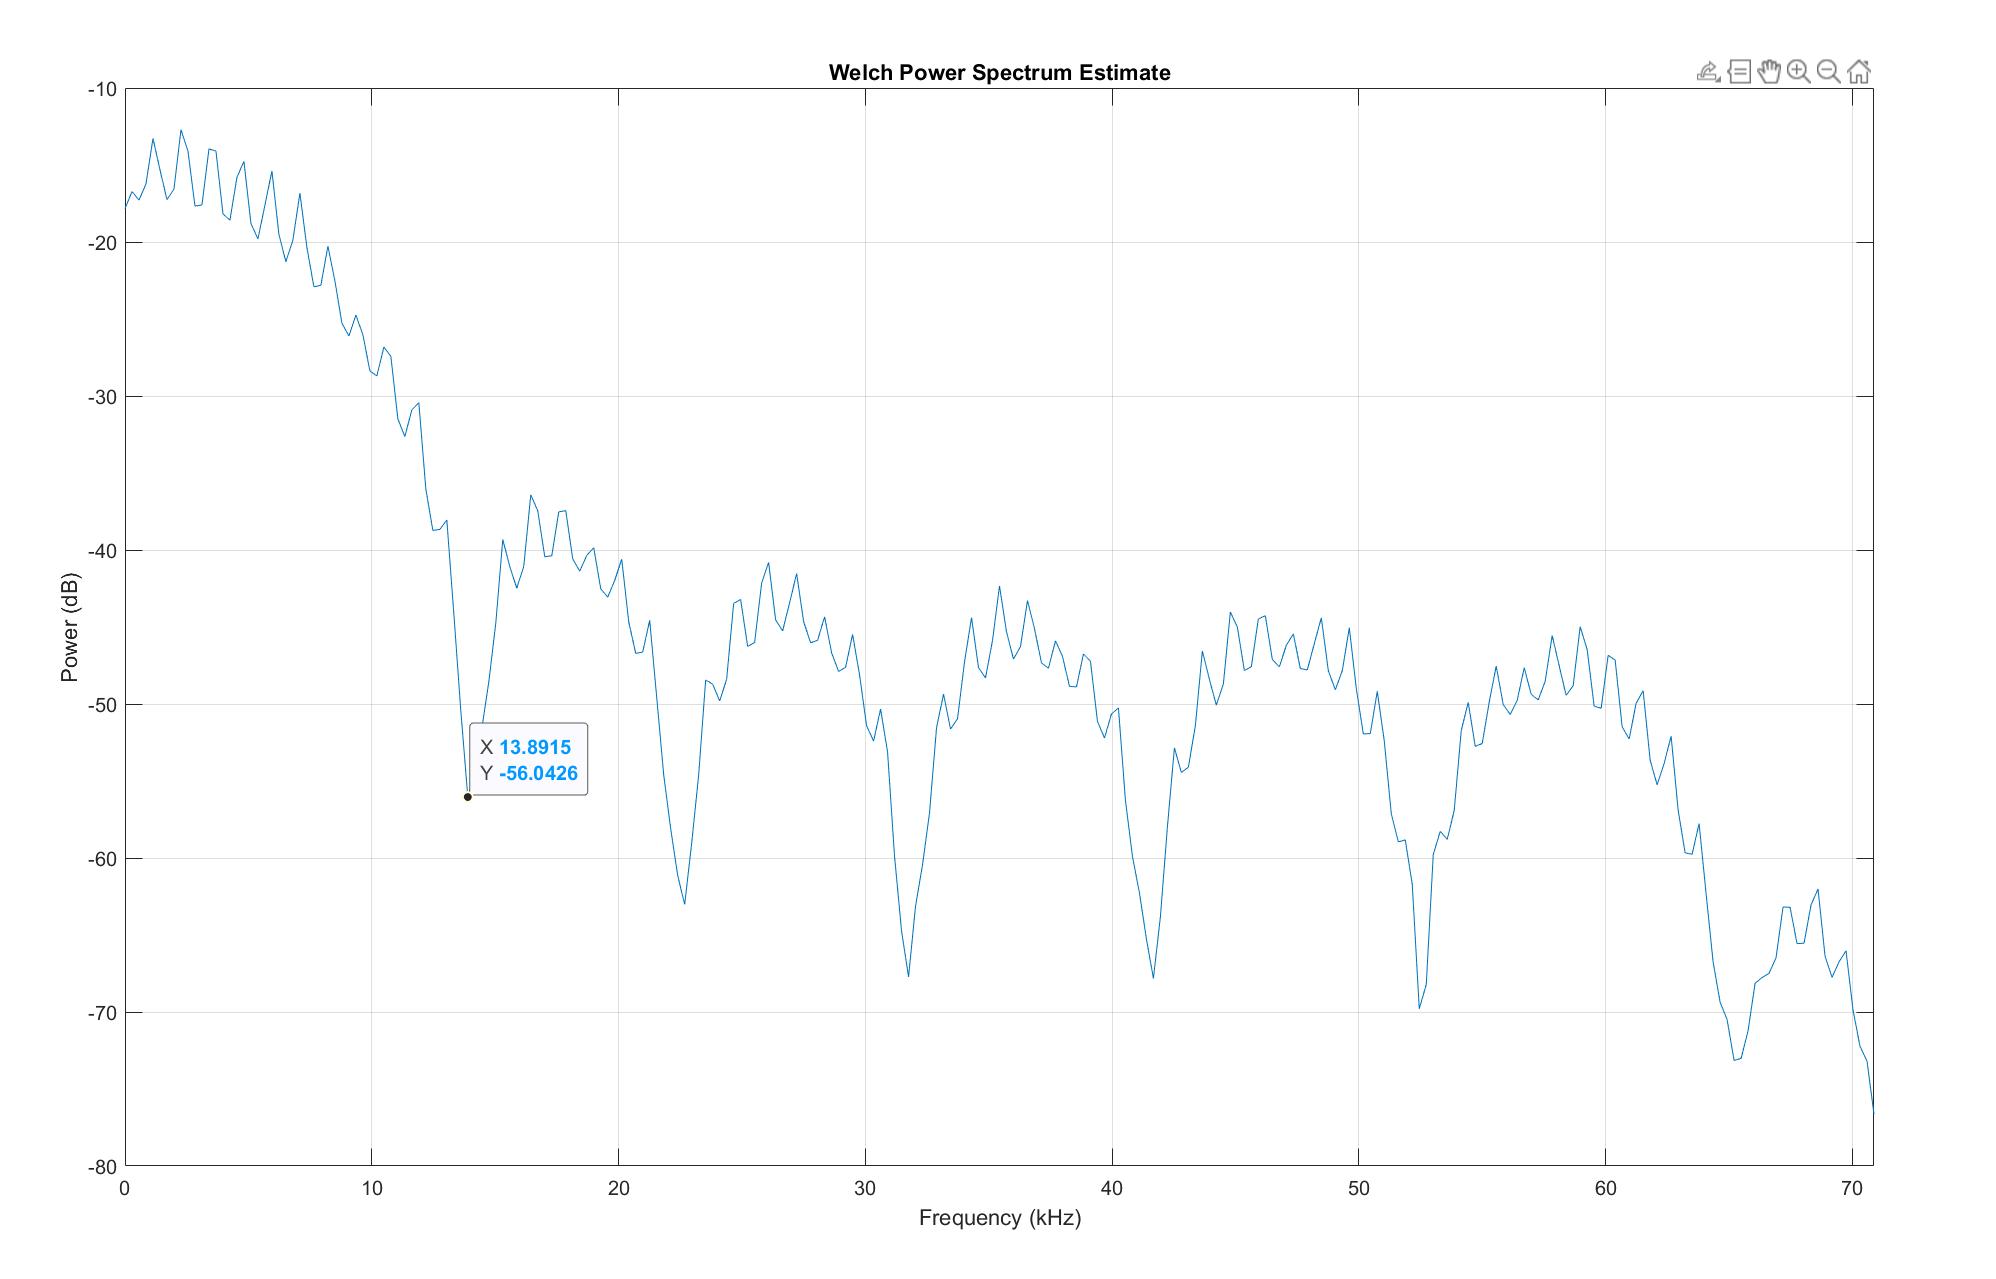

## Ejercicio 8

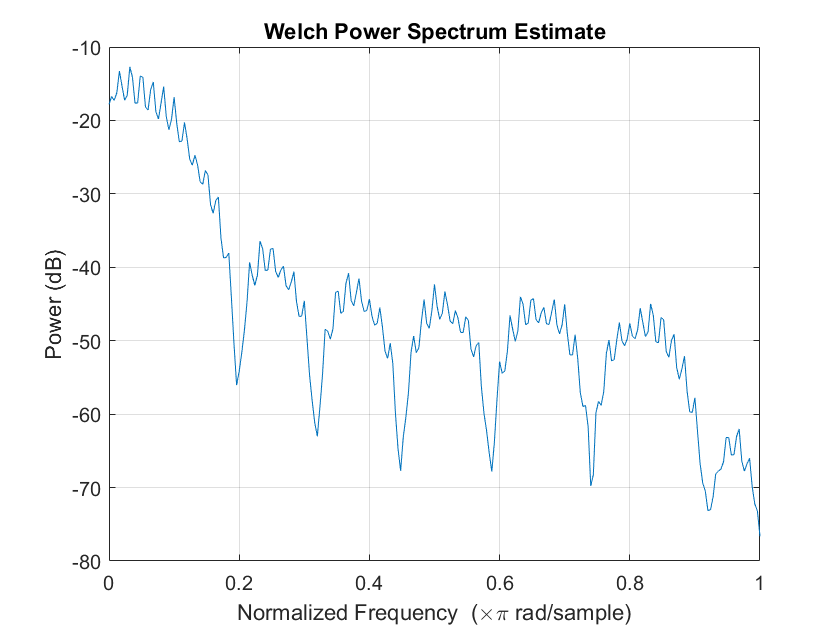

pwelch(xPNRZ,500,300,500,'power');

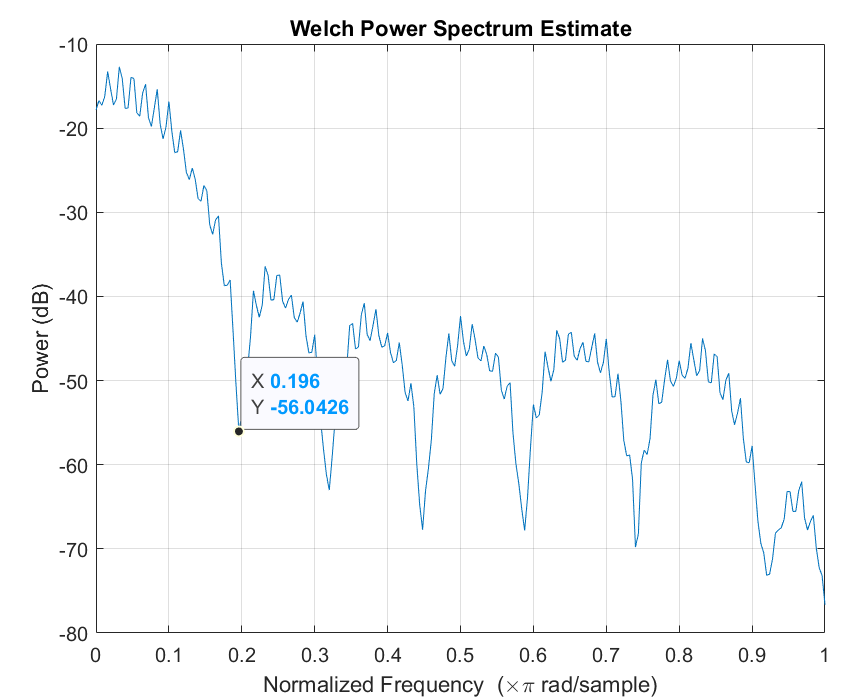

%%normalizado 0.196pi

Fc = 0.196 + 0.022

Fc = 0.2180

f = [0, Fc, Fc, 1];
m = [1, 1, 0, 0];
LPF = fir2(60, f, m);

fvtool(LPF);



## Ejercicio 9